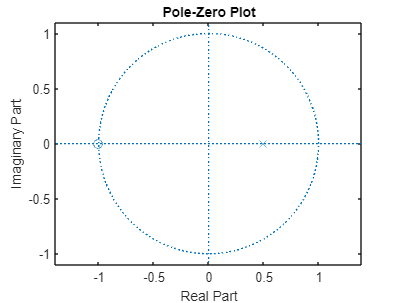

a = [1 -1/2]; %coefficients of y(n) - 1/2y(n-1)
b = [1 1]; %coefficients of x(n) + x(n-1)

%the difference equation is then
%y(n) = 1/2y(n-1) + x(n)
%note that the order here in z transform is in z^-1

% note that H(z) is causal
% H(z) = z + 2 = (1 + 2z^-1) / (z^-1) --> b = [1 2], a = [0 1]

zplane(b,a)

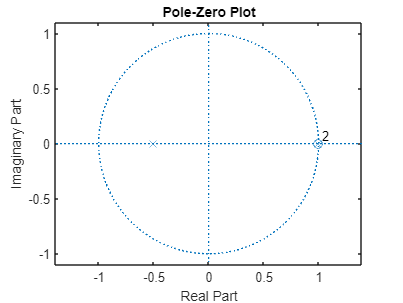

%this is the version we want to use for filters!
%note that a is the pole at 1/2, z^-1 is the reason for the zero at origin
figure;
zplane(b', a') %this is not the form we want to use! don't use!!!

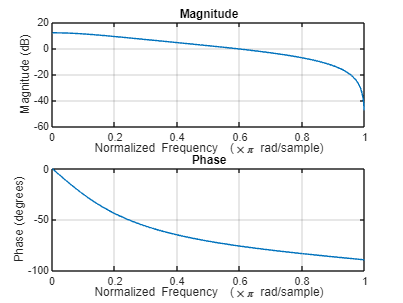


%y = filter(b,a,x)
freqz(b,a) 